clear

addpath("matlab_functions\")

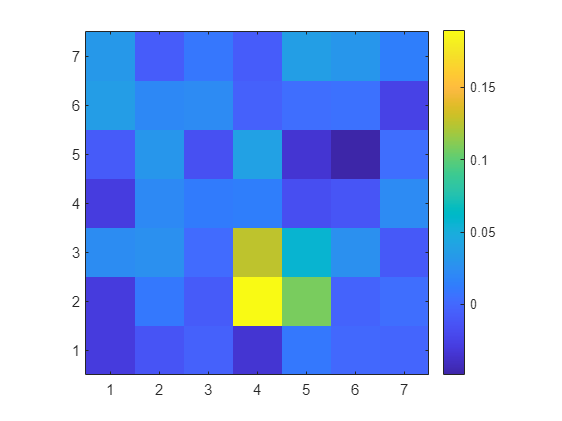

N = 20; % image width

h = 5;
kernel = fspecial('average',h);

idx = reshape(1:N^2, N,N);

A = sparse(N^2);
offset = -ceil(h/2);
row = 1;
for y = 1:3:N
for x = 1:3:N
    for p = 1:h
    for q = 1:h
        i = x + p + offset;
        i = min(max(i,1), N);
        j = y + q + offset;
        j = min(max(j,1), N);
        A(row, idx(i,j)) = kernel(p,q);
    end
    end
    row = row + 1;
end
end
clear h kernel idx offset x y p q i j row

x = zeros(N^2,1);
x(70:71) = 1;
x(90:91) = 1;

y = A * x;
y = y + normrnd(0, 0.02, size(y));

figure
imagesc(reshape(y,sqrt(length(y)),[]).')
colorbar
axis square xy

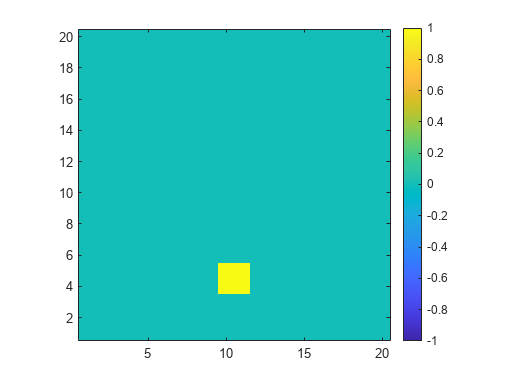


figure
imagesc(reshape(x,N,N).', [-max(x) max(x)])
colorbar
axis square xy

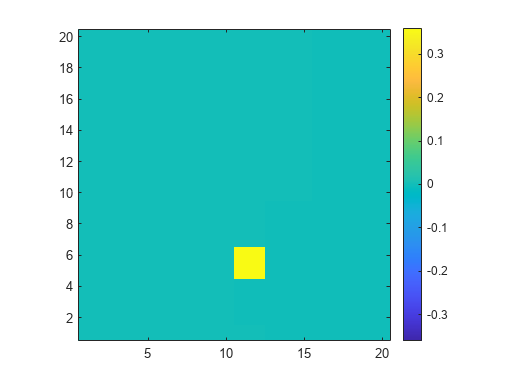


reg{1}.lambda = 1e-2;
reg{1}.L = speye(N^2);
x1 = L1Regularize(A,y, reg, 1e-2);
clear reg

figure
imagesc(reshape(x1,N,N).', [-max(x1) max(x1)])
colorbar
axis square xy

[r1,r2,r3] = ndgrid(1:N,1:N,1);
element_centers = [reshape(r1,1,[]); reshape(r2,1,[]); reshape(r3,1,[])];
b = 2;
Psi = ElementsOperation('BlockGroup', element_centers, b,b,1);

[x2, gamma] = BlockSBL(A,y, 'BlockLength',b^2, 'StructureAwareMatrix',Psi, ...
    'ShareCorrelationMatrix',false, 'MaxIterations',1000, 'Tolerance',1e-4);

    0.0015

    0.1435

    0.1459

    0.1458

    0.1458

    0.1457

    0.1456

    0.1455

    0.1454

    0.1453

    0.1452

    0.1450

    0.1449

    0.1448

    0.1447

    0.1446

    0.1445

    0.1443

    0.1442

    0.1441

    0.1439

    0.1438

    0.1437

    0.1435

    0.1434

    0.1432

    0.1431

    0.1429

    0.1428

    0.1426

    0.1425

    0.1423

    0.1422

    0.1420

    0.1419

    0.1417

    0.1415

    0.1414

    0.1412

    0.1410

    0.1409

    0.1407

    0.1406

    0.1404

    0.1402

    0.1401

    0.1399

    0.1397

    0.1396

    0.1394

    0.1392

    0.1390

    0.1389

    0.1387

    0.1385

    0.1384

    0.1382

    0.1380

    0.1379

    0.1377

    0.1375

    0.1373

    0.1372

    0.1370

    0.1368

    0.1367

    0.1365

    0.1363

    0.1362

    0.1360

    0.1358

    0.1356

    0.1355

    0.1353

    0.1351

    0.1349

    0.1348

    0.1346

    0.1344

    0.1343

    0.1341

    0.1339

    0.1337

    

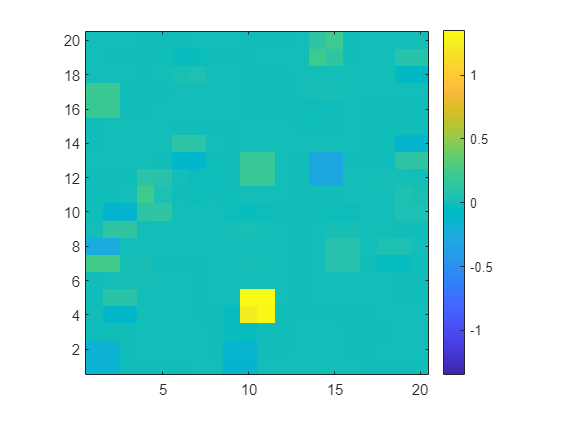

clear r1 r2 r3 element_centers b Psi

figure
imagesc(reshape(x2,N,N).', [-max(x2) max(x2)])
colorbar
axis square xy